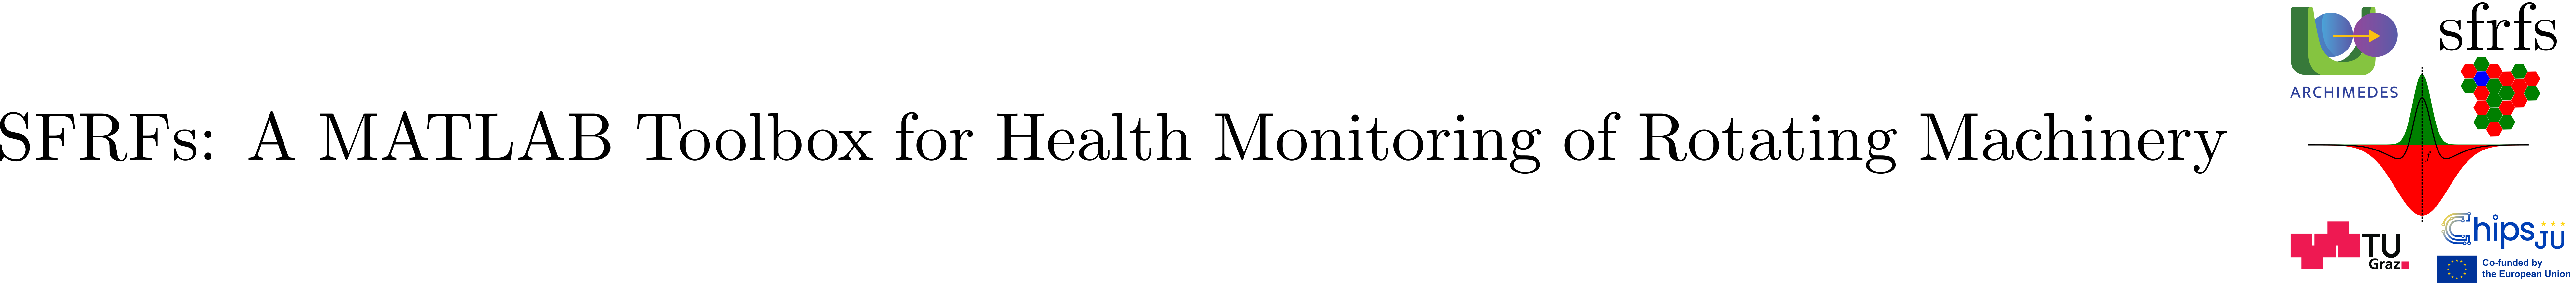

# BearingFrequencyBands

## Summary

`BearingFrequencyBands` is a concrete subclass of [`FaultFrequencyBands`](matlab:open('./FaultFrequencyBands.mlx')) that computes characteristic frequency bands for rolling-element bearing faults using bearing geometry and Spectral Fault Receptive Field (SFRF) parameters.

**Key features:**

- Computes fault frequency bands for outer race, inner race, rolling element (ball spin), and cage faults.

- Utilizes bearing geometry parameters, including number of rolling elements, ball diameter, pitch diameter, and contact angle.

- Supports configurable harmonics, sidebands, and Gaussian bandwidths on a per-fault basis through SFRF parameterization.

- Exposes constant fault frequency codes and fault group mappings compatible with MATLAB’s `bearingFaultBands` convention.

- Implements dedicated, fault-specific band generation methods, with automatic filtering of physically invalid (negative) frequency ranges.

- Produces standardized, human-readable fault labels following established bearing diagnostics notation.

- Integrates operating conditions and SFRF parameters to generate a structured table of fault frequency bands for downstream analysis.

- Includes built-in logging for traceability of the band computation process.

This class provides the core bearing-specific implementation within the SFRF framework and serves as a foundational component for rolling-element bearing fault detection, diagnosis, and spectral characterization.

## Description

`BearingFrequencyBands` is a concrete subclass of [`FaultFrequencyBands`](matlab:open('./FaultFrequencyBands.mlx')) that computes characteristic frequency bands associated with rolling-element bearing faults. It combines bearing geometry, operating conditions, and Spectral Fault Receptive Field (SFRF) parameters to generate structured representations of fault-related frequency bands, including harmonic and sideband components.

The class encapsulates both the physical bearing model and the signal-side configuration required to construct frequency bands that are compatible with MATLAB’s `bearingFaultBands` convention. It provides a standardized interface for producing center and surround frequency ranges associated with each fault type, enabling consistent downstream use in feature extraction, monitoring, and diagnostic pipelines.

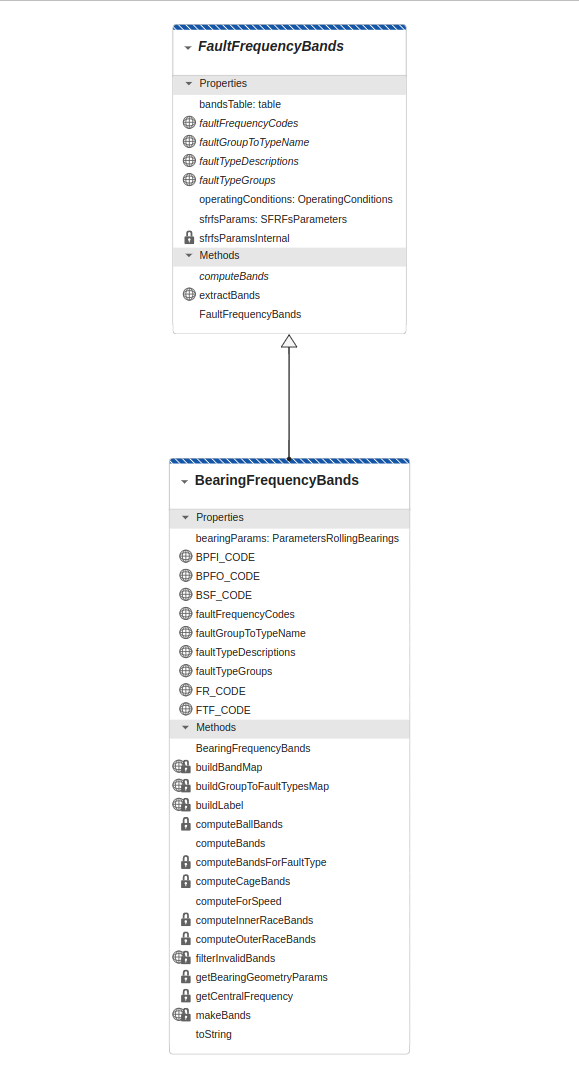

**Figure 1**. `BearingFrequencyBands` extends abstract class `FaultFrequencyBands`.

Figure 1 depicts the inheritance relationship between `BearingFrequencyBands` and the abstract base class [`FaultFrequencyBands`](matlab:open('./FaultFrequencyBands.mlx')). The SFRFs toolbox does not assume that the monitored frequencies necessarily originate from bearings; however, it provides explicit support for computing their characteristic frequencies. In this respect, the [`BearingFrequencyBands`](matlab:open('../../BearingFrequencyBands.m')) class serves as a reference implementation for other powertrain components.

### Bearing-Specific Metadata

The class defines short fault frequency code constants (Fo, Fi, Fb, Fc, Fr) and a corresponding collection, `faultFrequencyCodes`, which groups these same codes for use during band generation and lookup operations. These codes and mappings are defined to be compatible with MATLAB’s [Predictive Maintenance Toolbox](https://www.mathworks.com/products/predictive-maintenance.html) and its function [`bearingFaultBands`](https://www.mathworks.com/help/predmaint/ref/bearingfaultbands.html).

### Core Functionality

`BearingFrequencyBands` implements the abstract `computeBands` method defined by `FaultFrequencyBands`. This method constructs a table of fault frequency bands for each combination of:

- Operating condition (speed and load)

- Fault type (outer race, inner race, ball, and cage)

- Harmonic index

- Sideband index

The resulting table contains, for each row:

- A numeric fault group identifier

- A human-readable fault description

- Operating speed

- Operating load

- A cell array of receptive field definitions (`ReceptiveFieldBands`)

Each receptive field is encoded as a `containers.Map` containing:

- A band definition (`Center` and `Surround` frequency ranges)

- The harmonic index

- The sideband index

- A formatted label in standard bearing-fault notation (for example, `2Fi+1Fr`)

### Band Generation Strategy

For each fault type, the class applies an appropriate physical model to compute the characteristic central frequency:

- BPFO and BPFI are derived from bearing geometry and shaft speed

- BSF and FTF are computed using the same geometry with fault-specific expressions

- Sidebands are generated via modulation with the shaft or cage frequency, depending on the fault type

Gaussian bandwidths, defined in the associated `SFRFsParametersRollingBearings` object, are applied symmetrically around each central frequency to form both:

- A center band

- A surround band

Any bands with negative frequency bounds are automatically discarded to ensure physical validity. For more details see [SFRFsParameters](matlab:open('./SFRFsParameters.mlx')).

### Integration with Operating Conditions

The class is designed to operate over multiple operating conditions. For each row in the associated [`OperatingConditions`](matlab:open('./OperatingConditions.mlx')) object, `BearingFrequencyBands` computes a complete set of fault frequency bands and aggregates the results into a single table. This supports batch processing across different speeds and loads while preserving a consistent representation. The method `computeForSpeed` may also be used independently to generate bands for a single shaft speed without populating the full table, making it suitable for ad hoc analysis or interactive use.

### Diagnostics and Traceability

Logging is integrated throughout the computation process via [`SFRFsLogger`](matlab:open('./SFRFsLogger.mlx')). Informational and fine-grained messages are produced during band generation, enabling traceability of parameters, operating points, and resulting bands. This supports reproducibility and aids debugging when integrating the class into larger monitoring or diagnostic pipelines.

### Intended Usage

`BearingFrequencyBands` is intended to serve as the bearing-specific implementation within the SFRF framework. It provides a consistent, extensible, and standards-aligned mechanism for translating physical bearing properties into spectral representations that can be used for:

- Fault detection

- Fault diagnosis

- Condition monitoring

- Feature construction

- Model-based and data-driven prognostics

It is typically instantiated with:

- Bearing geometry (`ParametersRollingBearings`)

- SFRF configuration (`SFRFsParametersRollingBearings`)

- Operating conditions (`OperatingConditions`)

After construction, frequency bands can be generated by calling `computeBands` for batch processing or `computeForSpeed` for a specific operating point.

### **See also**

[`FaultFrequencyBands`](matlab:open('./FaultFrequencyBands.mlx')), [`ParametersRollingBearings`](matlab:open('./ParametersRollingBearings.mlx')), [`SFRFsParametersRollingBearings`](matlab:open('./SFRFsParametersRollingBearings.mlx')), [`OperatingConditions`](matlab:open('./OperatingConditions.mlx')), [`ReceptiveFieldGainFunctions`](matlab:open('./ReceptiveFieldGainFunctions.mlx'))`, and MATLAB's `[`bearingFaultBands`](https://www.mathworks.com/help/predmaint/ref/bearingfaultbands.html)`.`

## Example

We illustrate the creation of the object using the parameters of the [**XJTU-SY**](https://github.com/WangBiaoXJTU/xjtu-sy-bearing-datasets) rolling bearing run-to-failure dataset (See Reference [2]).

% Create geometric parameters of the bearing
bp = ParametersRollingBearings( ...
    numRollingElements = 8, ...
    ballDiameter = 7.92, ...
    pitchDiameter = 34.55, ...
    contactAngle = 0);

% Create shared SFRF params for all fault types
sharedParams = ...
    SFRFsParametersRollingBearings.createSFRFsParameters(...
    'order',           3, ...
    'numSidebands',    2, ...
    'numHarmonics',    3, ...
    'sigmaCenter',     [5, 7], ...
    'sigmaSurround',   [12, 3], ...
    'inhibitionFactor', 0.5 );

sfrfsParams = SFRFsParametersRollingBearings( ...
    SameForAllFaultTypes = sharedParams);

% Create operating conditions
speed = [35; 37.5; 40];
load  = [12; 11; 10];

oc = OperatingConditions(speed, load);

% Create BearingFrequencyBands object
bfb = BearingFrequencyBands( ...
    bearingParams = bp, ...
    sfrfsParams = sfrfsParams,...
    operatingConditions = oc)

bfb =   BearingFrequencyBands with properties:

            bearingParams: [1×1 ParametersRollingBearings]
                BPFO_CODE: 'Fo'
                BPFI_CODE: 'Fi'
                 BSF_CODE: 'Fb'
                 FTF_CODE: 'Fc'
                  FR_CODE: 'Fr'
      faultFrequencyCodes: {'Fo'  'Fi'  'Fb'  'Fc'}
    faultTypeDescriptions: [4×1 containers.Map]
          faultTypeGroups: [4×1 containers.Map]
     faultGroupToTypeName: [4×1 containers.Map]
              sfrfsParams: [1×1 SFRFsParametersRollingBearings]
      operatingConditions: [1×1 OperatingConditions]
               bandsTable: [0×0 table]


## API documentation

### MATLAB help

help BearingFrequencyBands

  BearingFrequencyBands  Compute bearing fault characteristic frequency 
    bands
 
    Computes characteristic and sideband frequency bands for bearing faults 
    based on bearing geometry and Spectral Fault Receptive Fields (SFRF) 
    parameters.
    Supports configurable harmonics, sidebands, and Gaussian bandwidths for 
    each fault type.
 
  Properties:
    bearingParams - ParametersRollingBearings object containing bearing 
                    geometry
    sfrfsParams   - SFRFsParametersRollingBearings object configuring SFRF 
                    settings
 
  Constant Properties:
    BPFO_CODE - Code for Ball Pass Frequency Outer Race ('Fo')
    BPFI_CODE - Code for Ball Pass Frequency Inner Race ('Fi')
    BSF_CODE  - Code for Ball Spin Frequency ('Fb')
    FTF_CODE  - Code for Fundamental Train Frequency (Cage) ('Fc')
    FR_CODE   - Code for Shaft Rotational Frequency ('Fr')
    faultFrequencyCodes - Cell array of all fault frequency codes used
 
  Example:
    % Define b

### MATLAB documentation

doc BearingFrequencyBands

Opens the full class documentation in the MATLAB Help Browser, including formatted examples, links to related functions, and extended descriptions.

## Source code

The source of this class can be found in [BearingFrequencyBands](matlab:open('../../BearingFrequencyBands.m')).

## Test

The unit test for this class can be found in [TestBearingFrequencyBands](matlab:open('../../../tests/TestBearingFrequencyBands.m')).

% execute tests
res = runtests('Spectral Fault Receptive Fields/tests/TestBearingFrequencyBands');

Running TestBearingFrequencyBands
.......... ........
Done TestBearingFrequencyBands
__________



% display summary of tests
SFRFsTestUtil.printTestSummary(res,80);

Test Name                                                                        | Result
-----------------------------------------------------------------------------------------
TestBearingFrequencyBands/testValidConstruction                                  | Passed
TestBearingFrequencyBands/testInvalidBearingParamsType                           | Passed
TestBearingFrequencyBands/testInvalidSfrfsParamsType                             | Passed
TestBearingFrequencyBands/testInvalidOperatingConditions                         | Passed
TestBearingFrequencyBands/testMissingBearingParamsArgument                       | Passed
TestBearingFrequencyBands/testMissingSFRSsParamsArgument                         | Passed
TestBearingFrequencyBands/testMissingOperatingConditionsArgument                 | Passed
TestBearingFrequencyBands/testComputeForSpeedKeysAndTypes                        | Passed
TestBearingFrequencyBands/testDescriptionsInAnswer                               | Passed
TestBearin

## How to cite this work

Muñoz Gutiérrez, Stan, & Wotawa, Franz (2025). SFRFs: A MATLAB Toolbox for Health Monitoring of Rotating Machinery. Zenodo. DOI: [10.5281/zenodo.17631784](http://10.0.20.161/zenodo.17631784).

## References

- [1] Stan Muñoz Gutiérrez and Franz Wotawa. Optimized Spectral Fault Receptive Fields for Diagnosis-Informed Prognosis. In 36th International Conference on Principles of Diagnosis and Resilient Systems (DX 2025). Open Access Series in Informatics (OASIcs), Volume 136, pp. 9:1-9:20, Schloss Dagstuhl – Leibniz-Zentrum für Informatik (2025) [DOI:10.4230/OASIcs.DX.2025.9](https://doi.org/10.4230/OASIcs.DX.2025.9).

- [2] Biao Wang, Yaguo Lei, Naipeng Li, Ningbo Li, “A Hybrid Prognostics Approach for Estimating Remaining Useful Life of Rolling Element Bearings”, IEEE Transactions on Reliability, pp. 1-12, 2018. [DOI: 10.1109/TR.2018.2882682](https://doi.org/10.1109/TR.2018.2882682).